# Prepare differentially expressed gene profiles from CCLE RNASeq dataset

## Summary

## Load Data

### Load metabolic reconstruction

clear all;
load ~/Data/Reconstructions/eGEM/07132020.mat; % Latest version of eGEM model
eGEM.geneEntrezID = regexprep(eGEM.genes, '\.[0-9]', '');
entrez = string(eGEM.geneEntrezID);

### Load RNASeq data

This RNASeq dataset contains the log2 fold change (tissue / median(all data)) and the p-value from the distribution.

filename = '~/Data/RNASeq/CCLE/Mapped_Processed_CCLE_effect.csv';
effect = readmatrix(filename);

filename = '~/Data/RNASeq/CCLE/Mapped_Processed_CCLE_pvalue.csv';
pvalue = readmatrix(filename);

### Get intersection between metabolic model and RNASeq data

We need to extract the effect sizes that are relevant for our dataset.

[~, ia, ib] = intersect(entrez, string(effect(:, 2)));
effect = effect(ib, :);
pvalue = pvalue(ib, :);

Read in the column names of the csv files.

filename = '~/Data/RNASeq/CCLE/colnames.csv';
fid = fopen(filename, 'rt');
colnames = textscan(fid, '%s', 'Delimiter',',');
fclose(fid);
colnames = colnames{1};

Reformat the data.

entrez_ids = pvalue(:, 2);
effect(:, 1:3) = [];
pvalue(:, 1:3) = [];
colnames(1:3) = [];

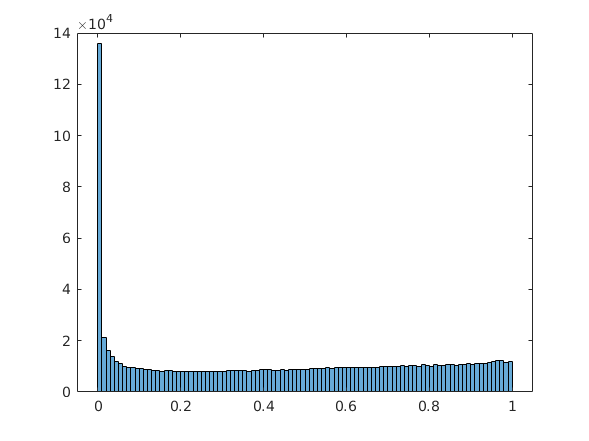

histogram(pvalue, 100)

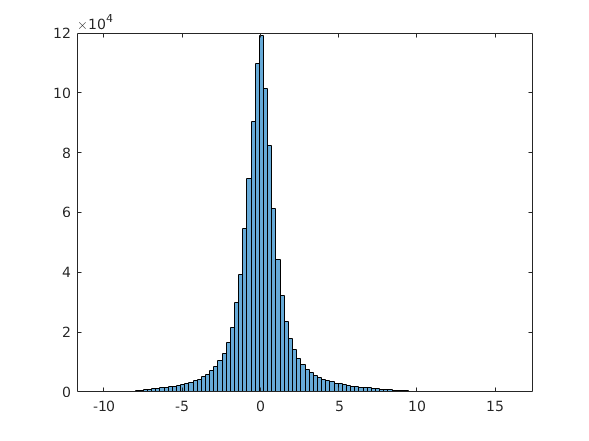

histogram(effect, 100)

cell_lines = colnames;
log2fc = effect;
clearvars -except cell_lines entrez_ids log2fc pvalue

save('~/Data/RNASeq/CCLE/CCLE_RNASeq.mat');